Playing hod_f.wav at 24000 Hz with duration 0.24 seconds and 5763 samples


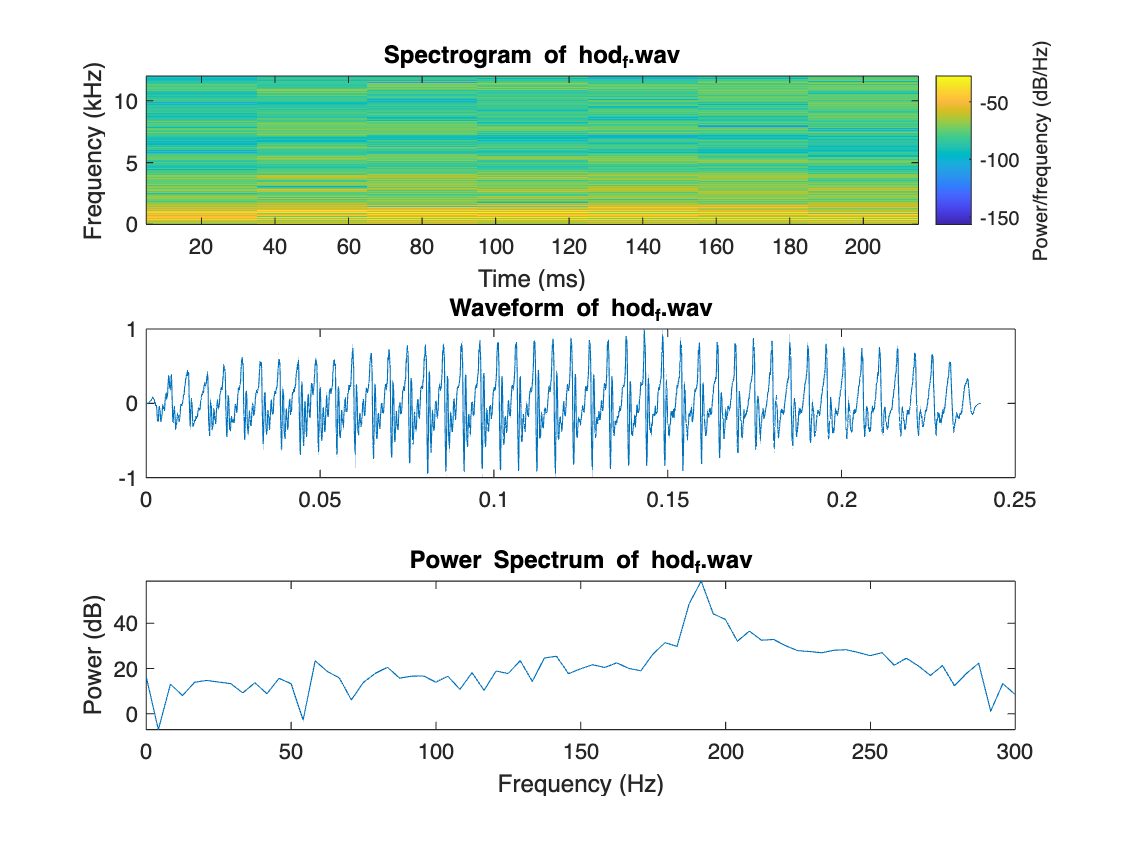

file_1 = 'hod_f.wav';
[audio, fs, duration, numSamples] = playAudio(file_1);

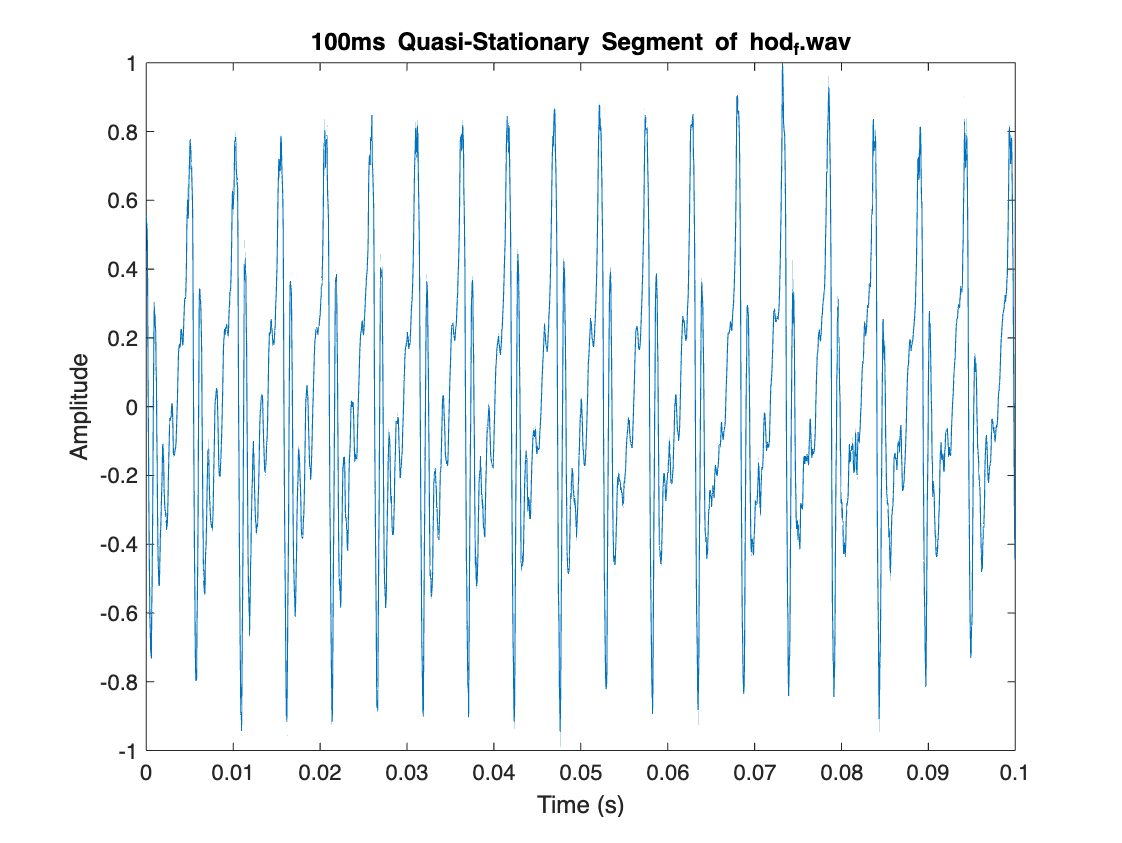

% select a 100ms quasi-stationary segment
segmentDuration = 0.1;
segment = extractCenterSegment(audio, fs, segmentDuration, file_1);

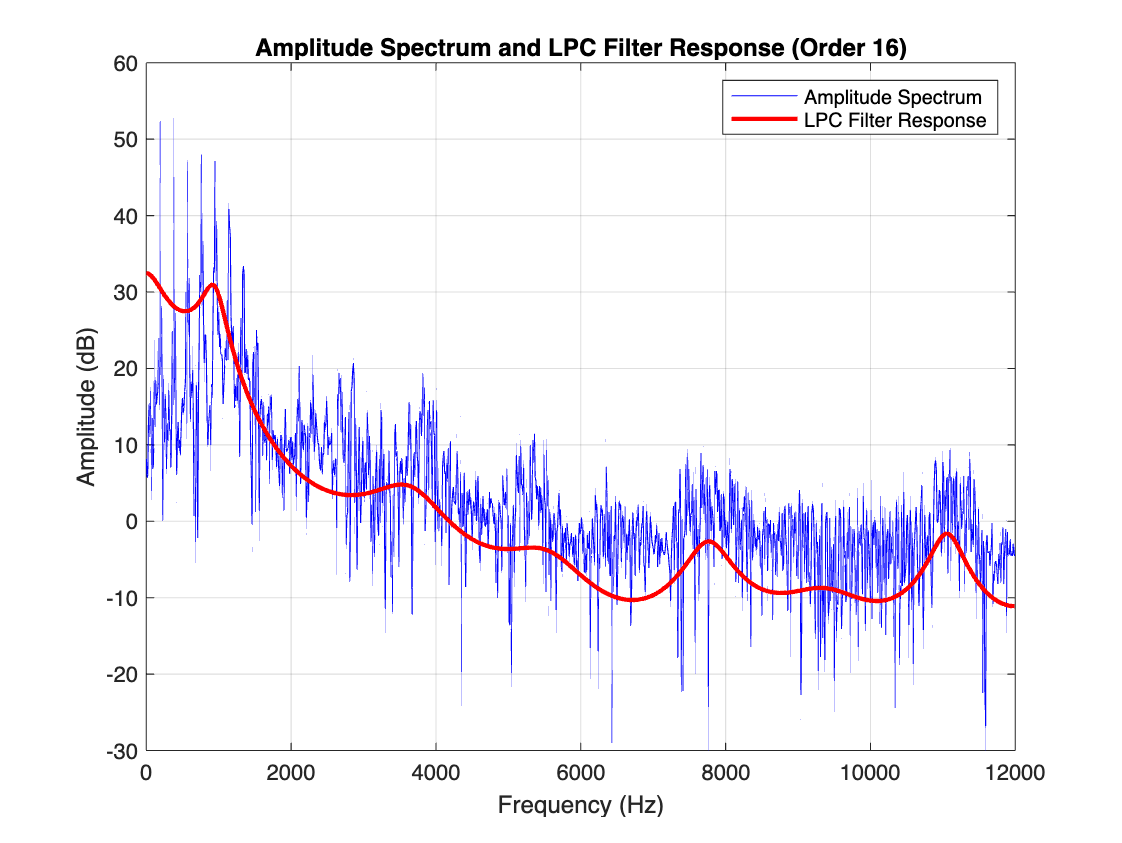

lpcOrder = 16;
plotLPCResponse(segment, fs, lpcOrder);

[formants] = estimateFormants(segment, fs, lpcOrder);

Estimated Formant Frequencies (Hz):
F1: 944.45 Hz
F2: 2859.99 Hz
F3: 3643.02 Hz


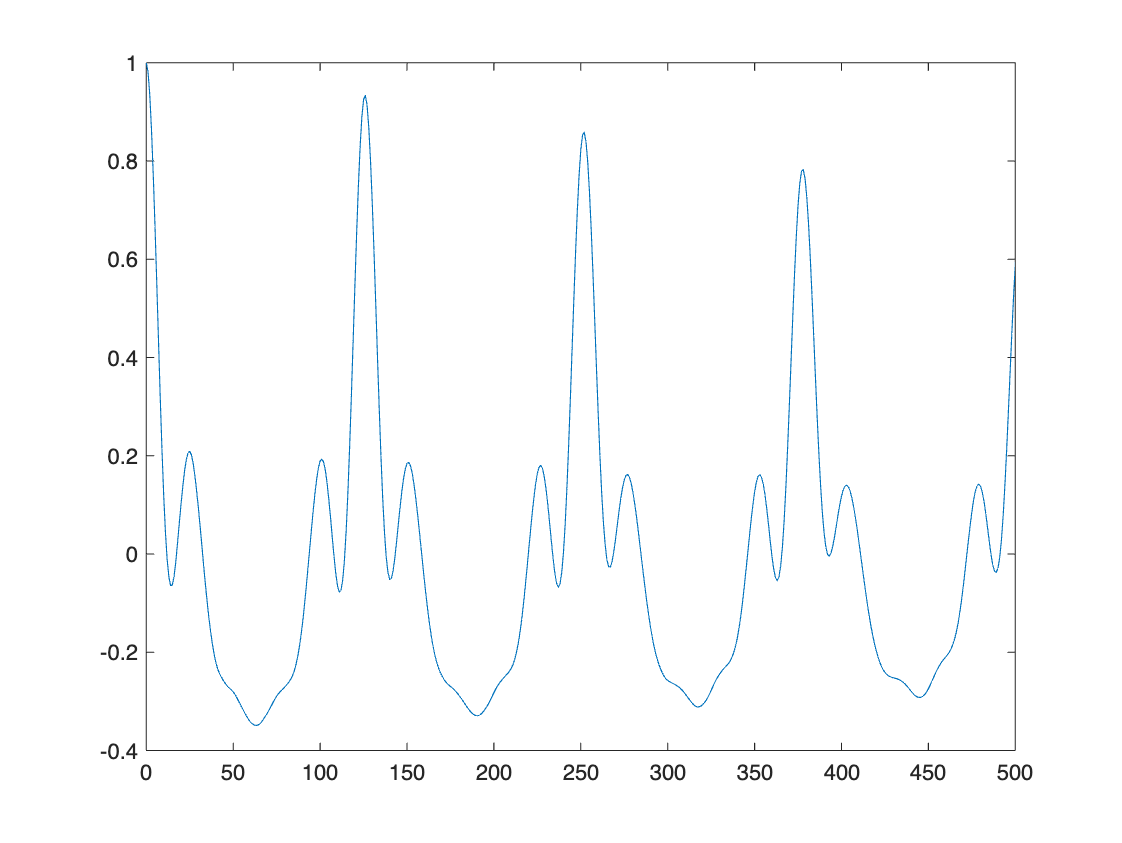

Estimated F0 using autocorrelation: 190.48 Hz


f0_estimate = estimateF0ByAutoCorrelation(segment, fs);

f0_power = estimateF0ByPowerSpectrum(segment, fs);

Estimated F0 using power spectrum: 190.00 Hz


f0 = mean(pitch(segment, fs, 'Range', [50 200]));
fprintf('Estimated F0 using pitch function: %.2f Hz\n', f0);

Estimated F0 using pitch function: 190.48 Hz


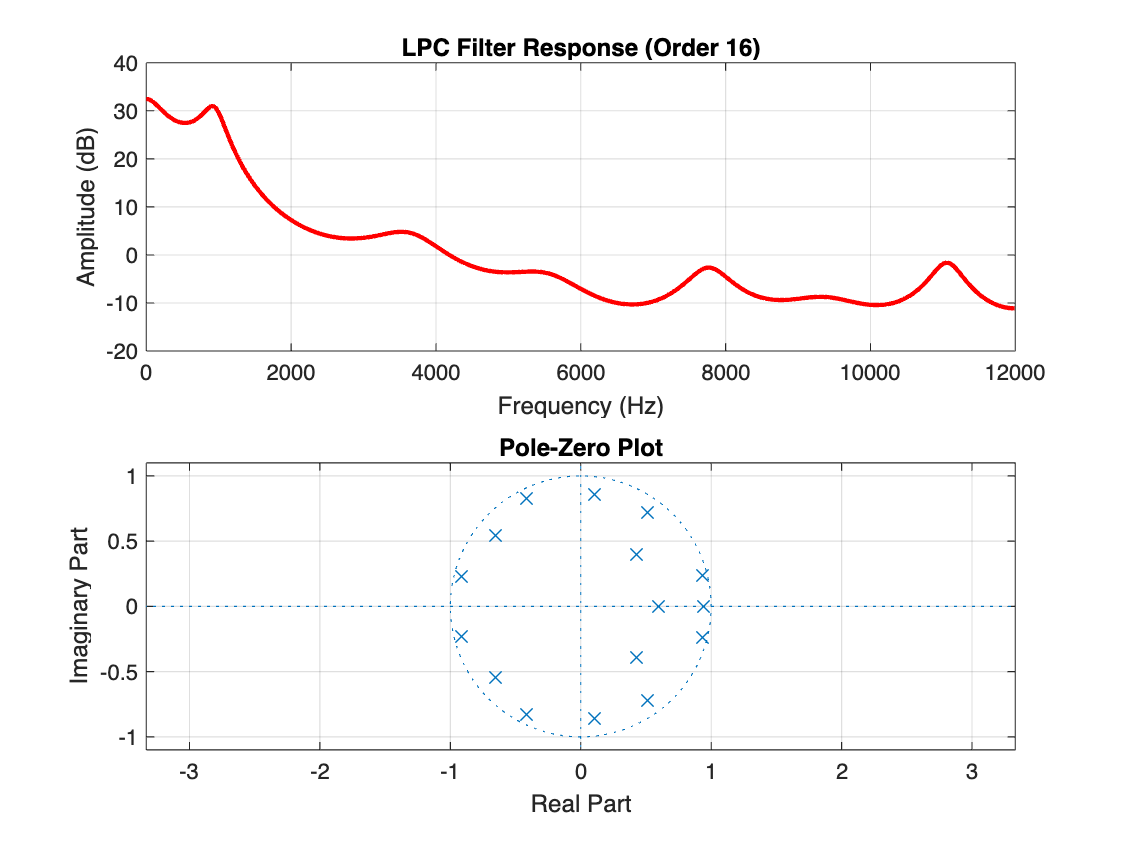

plotLPCPoleZero(segment, fs, lpcOrder);

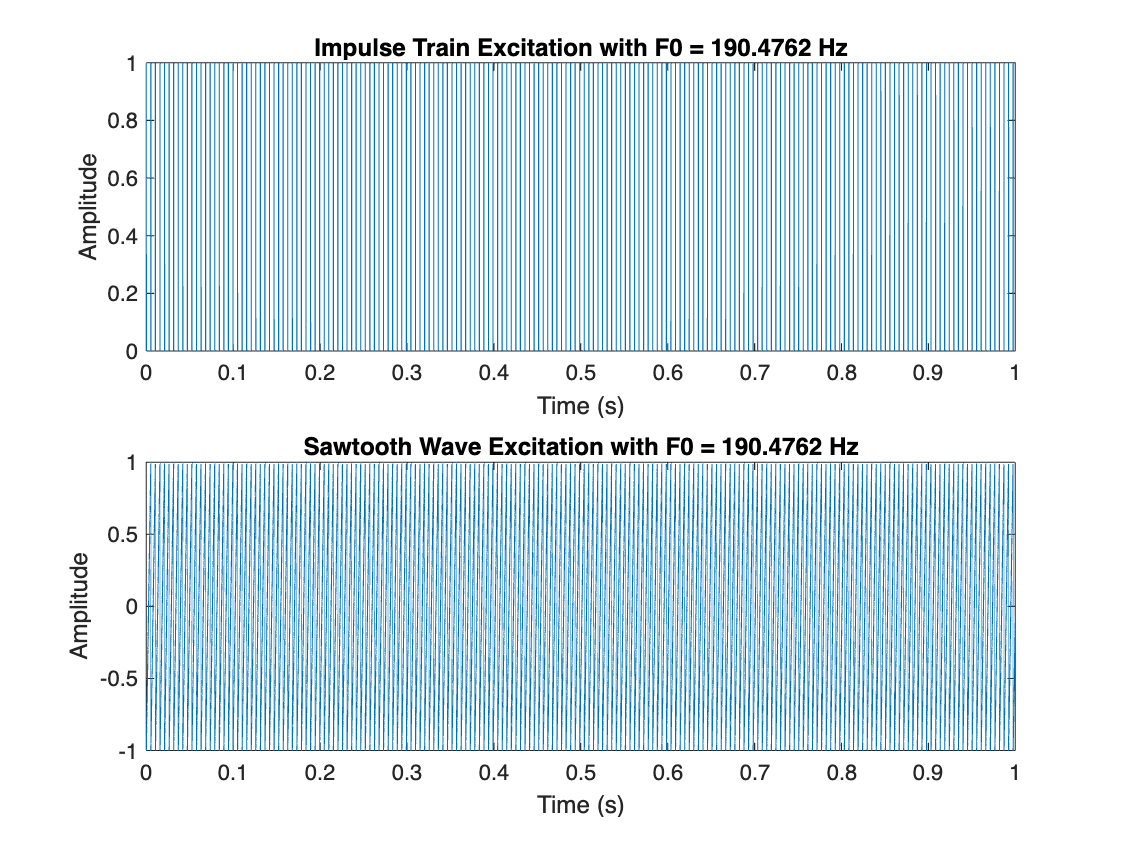

[synthesizedImpulse, synthesizedSawtooth] = synthesizeLPC(segment, fs, f0_estimate, lpcOrder, 1);

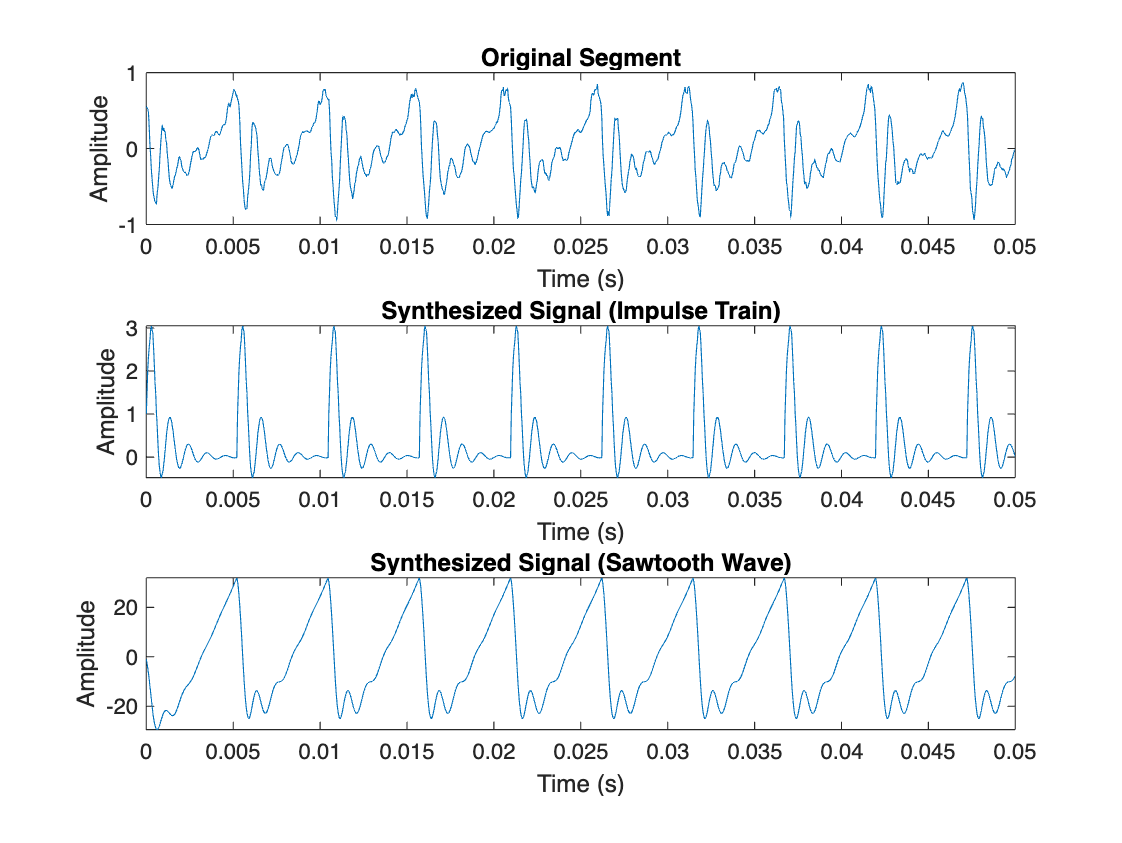

plotSynthesis(segment, fs, synthesizedImpulse, synthesizedSawtooth);